# indentSine

This live script is continuation of calciumPlot.mlx and applied to the vibration stimuli with fixed force

#### Load the indenter stimulation file

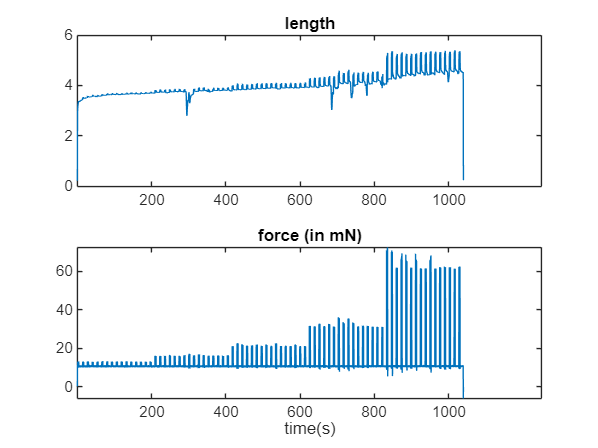

folderNameTemp = strsplit(path,filesep);
folderName = folderNameTemp{end-1};
clear folderNameTemp
close all
[filenameMat,pathMat] = uigetfile('\\research.files.med.harvard.edu\Neurobio\GintyLab\Qi\stimulation\indenter\*.mat',...
    ['select an indentation file for   ', folderName]);

% [filenameMat,pathMat] = uigetfile('C:\Users\Qi_Li\Dropbox (HMS)\LQCalciumImaging\stimulation\indenter\*.mat', ...
%     ['select an indentation file for
load([pathMat,filenameMat])
force = data(:,3);
down = 10;
figure,
tick = floor(numel(force)/Fs/5/10)*10;
% subplot(311),plot(cameraTrigger(1:10:end)),title('Trigger'),
subplot(211),plot(data(1:down:end,2)),title("length");
xticks(tick*Fs/down:tick*Fs/down:numel(force)/down)
xticklabels(strsplit(num2str(tick: tick: floor(numel(force)/Fs))));
subplot(212),plot(data(1:down:end,3)*50),title("force (in mN)");
xticks(tick*Fs/down:tick*Fs/down:numel(force)/down)
xticklabels(strsplit(num2str(tick: tick: floor(numel(force)/Fs))));
xlabel('time(s)')

% plot(force),title("force")
% pbaspect([3 1 1])
% set(gcf, 'Units', 'Normalized', 'OuterPosition', [0, 0.04, 1, 0.96]);
% nUnit = ceil(length(I)/nSweep);

#### Split the indenter file

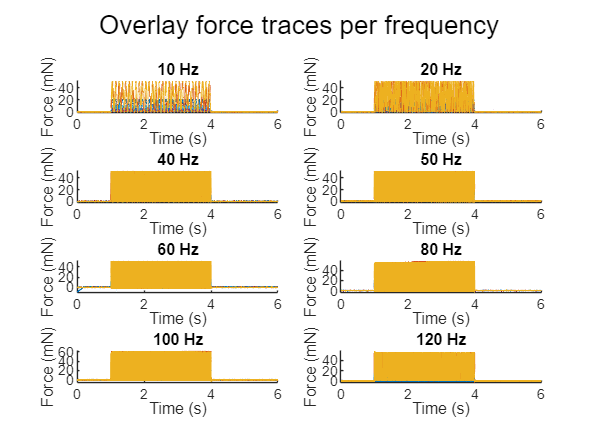

% --- prepare sizes ---
triggerDuration = sweepDuration + baseline + decayTime;
numSweeps = size(sineBoth,1);
voltageConversion = 50;
samplesPerSweep = Fs*(triggerDuration + interSweepInterval);   % matches fullForceTemp rows
activeStart = Fs*baseline + 1;
activeLen   = Fs * sweepDuration;
activeIdx   = activeStart : (activeStart + activeLen - 1);
baselineIdx = 1:(activeStart-1);
% recorded force vector (from your data). adjust column index if different
recordedForce = data(:,3);          % recorded analog force (volts)

% reshape back into matrix: rows = samplesPerSweep, cols = sweeps
recForceMat = reshape(recordedForce, samplesPerSweep, numSweeps);

Force_freq = zeros(samplesPerSweep*nRepeat*length(sineAmplitude),length(sineFrequency));

for i = 1:length(sineFrequency)
    freq_idx = find(sineBoth(:,2)== sineFrequency(i));
    force_temp = recForceMat(:,freq_idx);
    baselineMean = mean(force_temp(baselineIdx,:), 1);
    force_temp = force_temp - baselineMean;
    Force_freq(:,i) = force_temp(:);
end


rows = 4;
cols = 2;

figure(1)
t = (0:samplesPerSweep-1)/Fs;

for i = 1:length(sineFrequency)
    
    tmp = reshape(Force_freq(:,i), samplesPerSweep, []);
    
    subplot(rows, cols, i)
    hold on
    
    for k = 1:size(tmp,2)
        p = plot(t, tmp(:,k)*voltageConversion, 'LineWidth', 0.8);
        p.Color(4) = 0.2;   % transparency (lower = more transparent)
    end
    
    xlim([0 6])
    title(sprintf('%d Hz', sineFrequency(i)))
    ylabel('Force (mN)')
    xlabel('Time (s)')
end

sgtitle('Overlay force traces per frequency');


% Construct a config struct for the function
cfg = struct();
cfg.Fs = Fs;
cfg.cameraTriggerRate = cameraTriggerRate;
cfg.baseline = baseline;
cfg.sweepDuration = sweepDuration;
cfg.decayTime = decayTime;
cfg.voltageConversion = voltageConversion;
cfg.sineBoth = sineBoth;
cfg.sineFrequency = sineFrequency;
cfg.sineAmplitude = sineAmplitude;   % force levels (mN)
cfg.recForceMat = recForceMat;
clearvars time cameraTrigger data Data force tmp t recordedForce force_temp Force_freq

####  Align the indentation with response and save the figure

nCell = 1

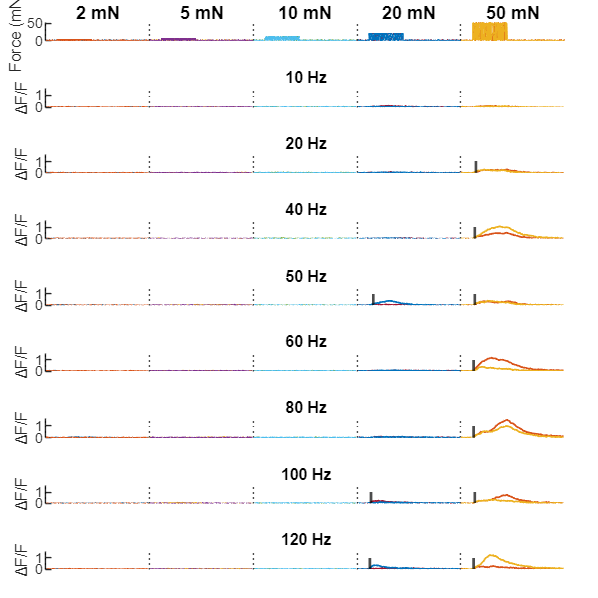

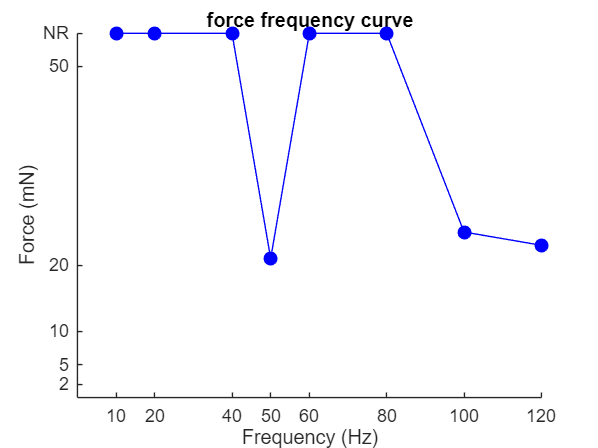

nCell = 2

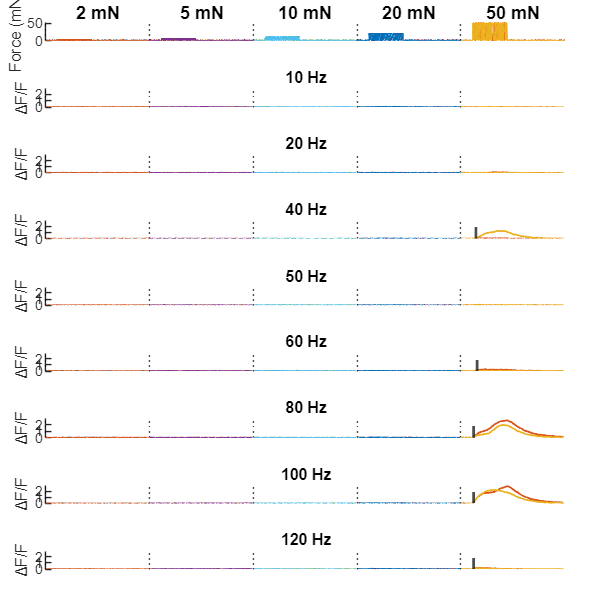

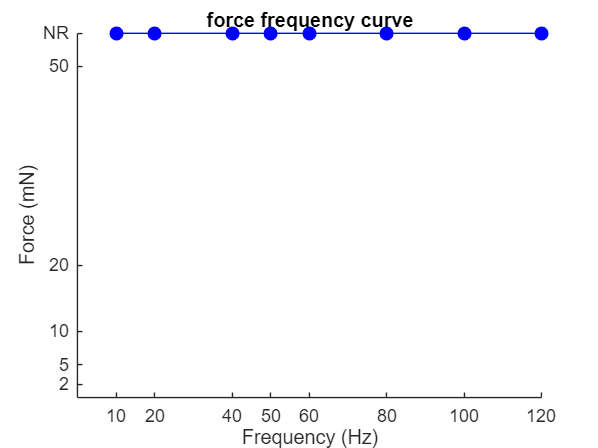

nCell = 3

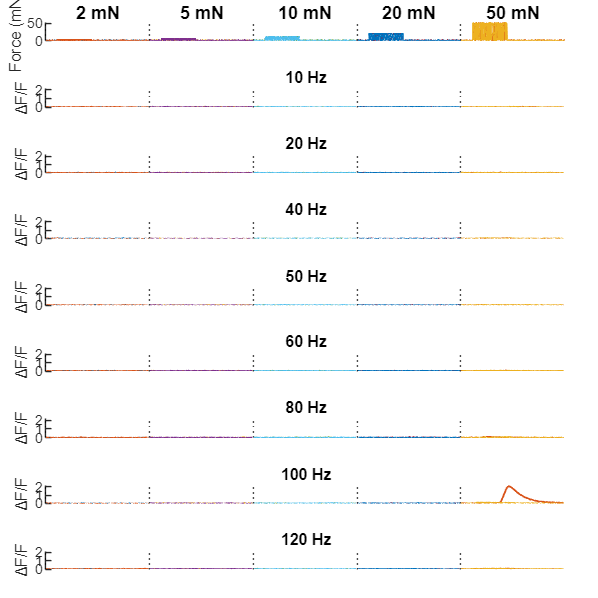

nCell = 4

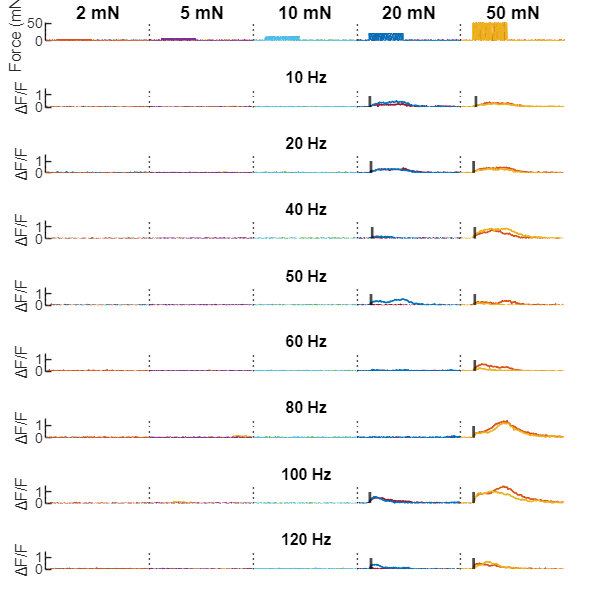

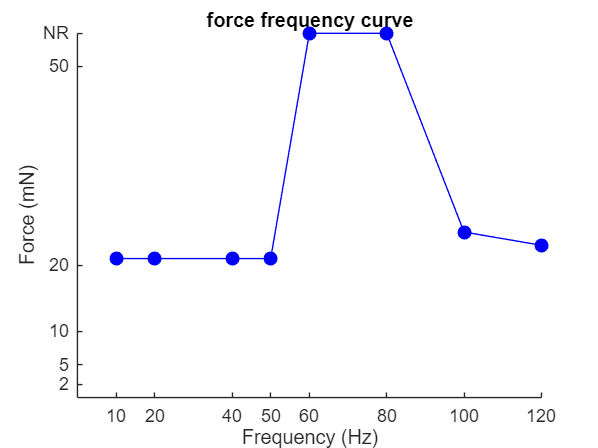

nCell = 5

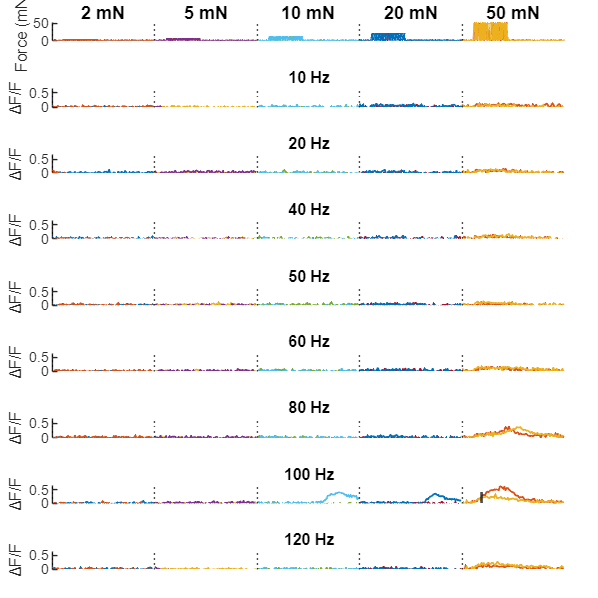

nCell = 6

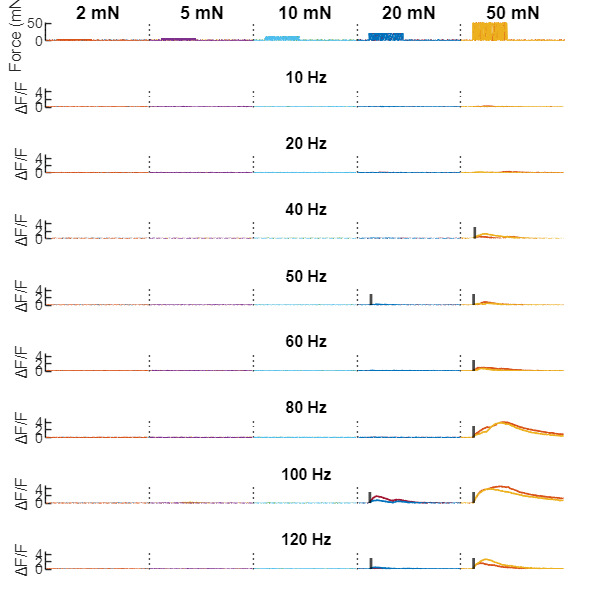

nCell = 7

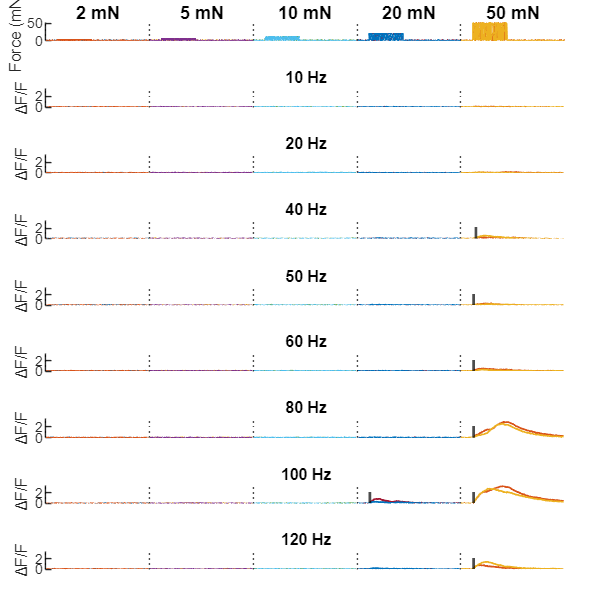

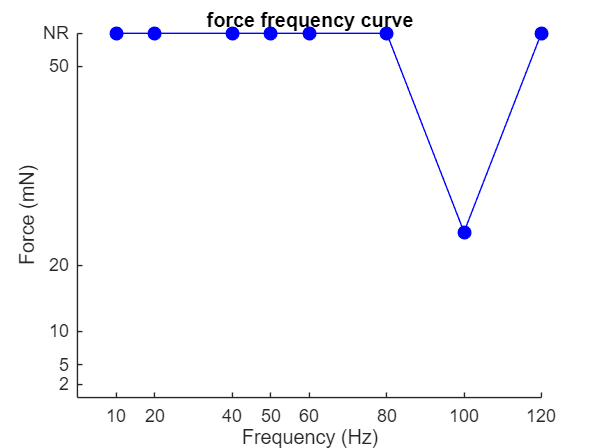

nCell = 8

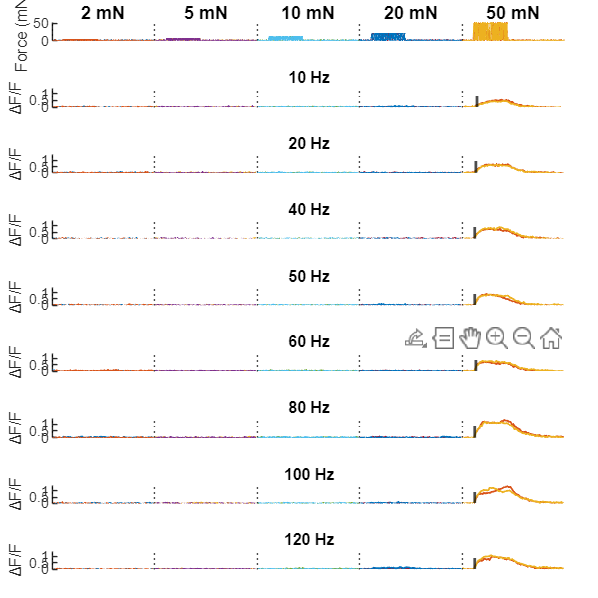

nCell = 9

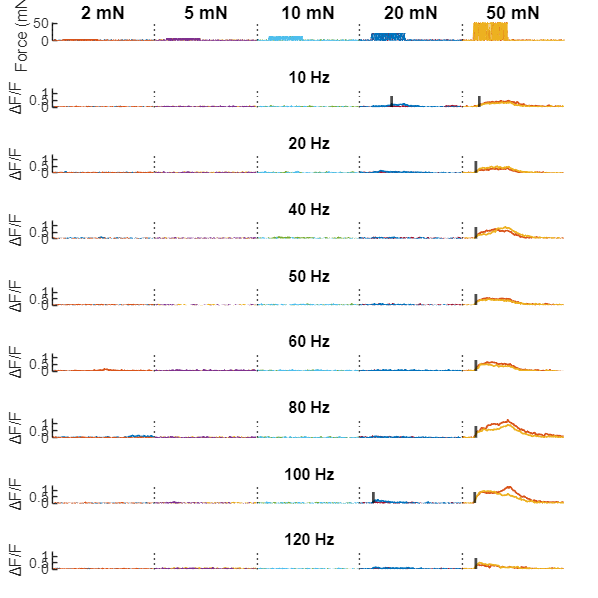

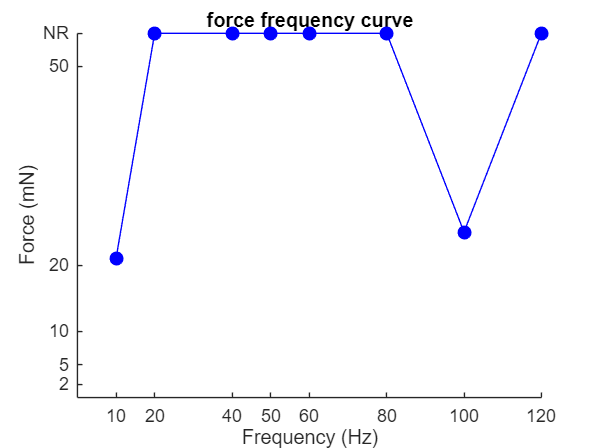

nCell = 10

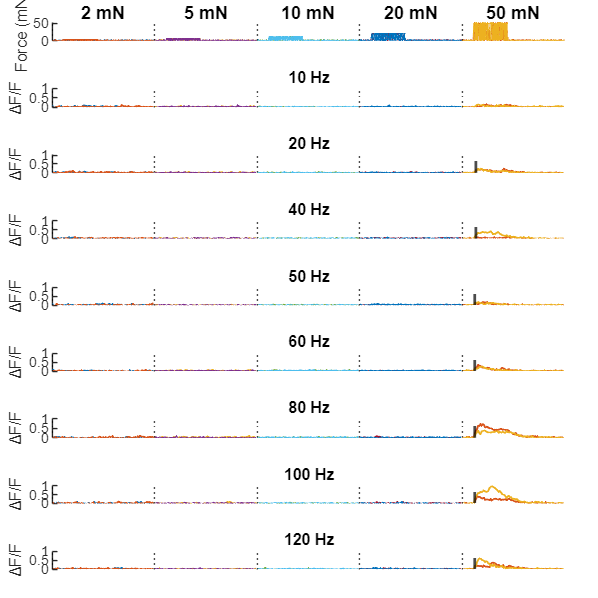

nCell = 11

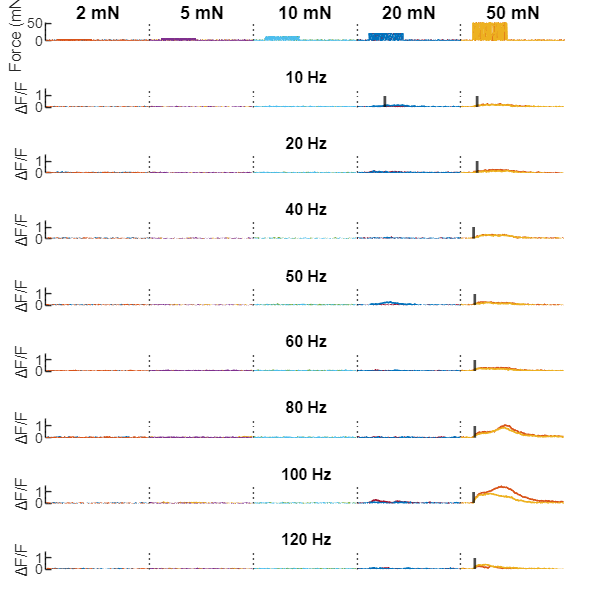

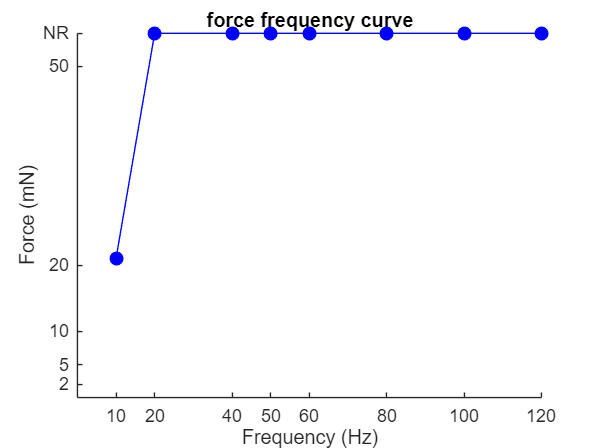

nCell = 12

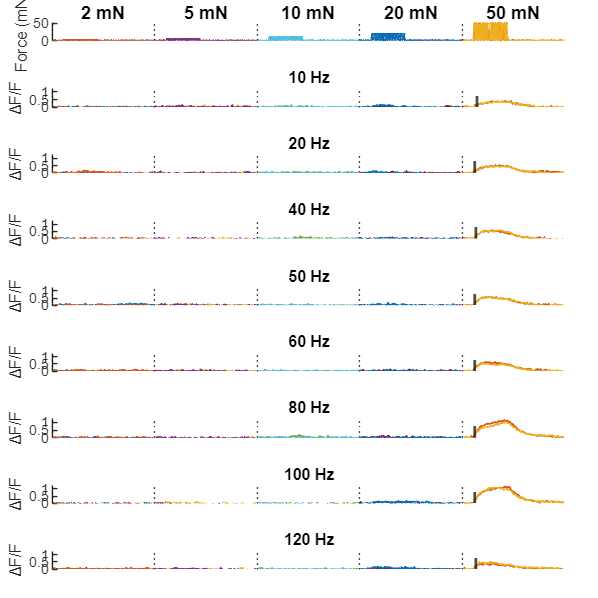

nCell = 13

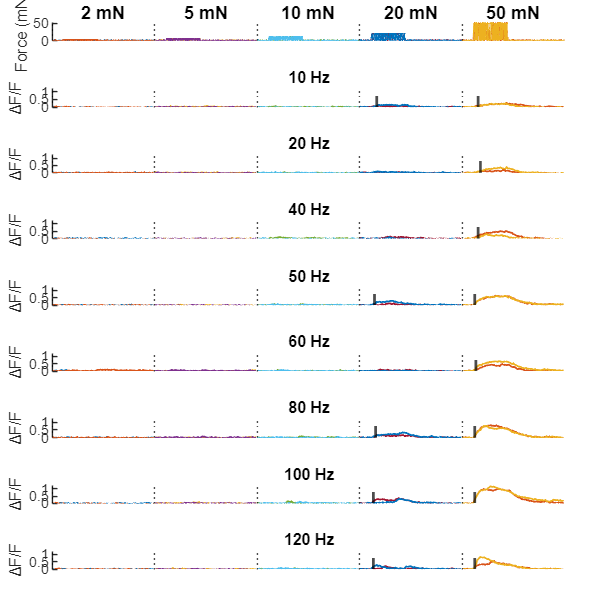

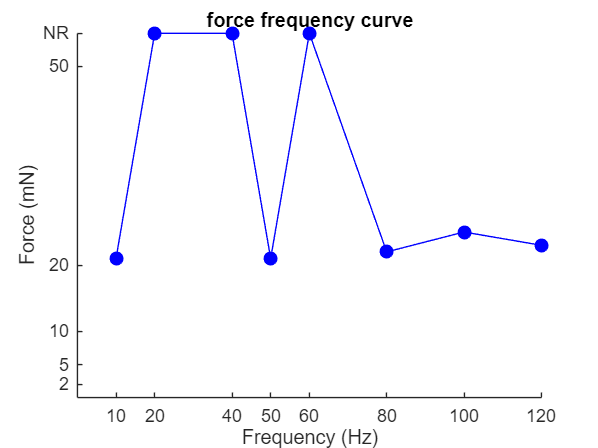

nCell = 14

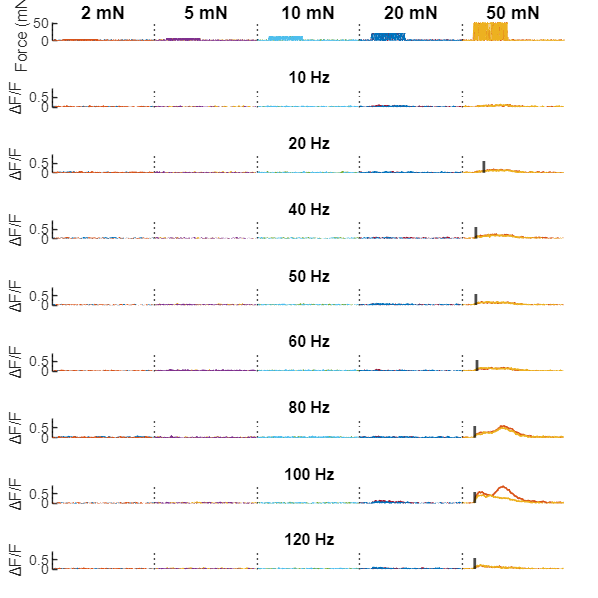

nCell = 15

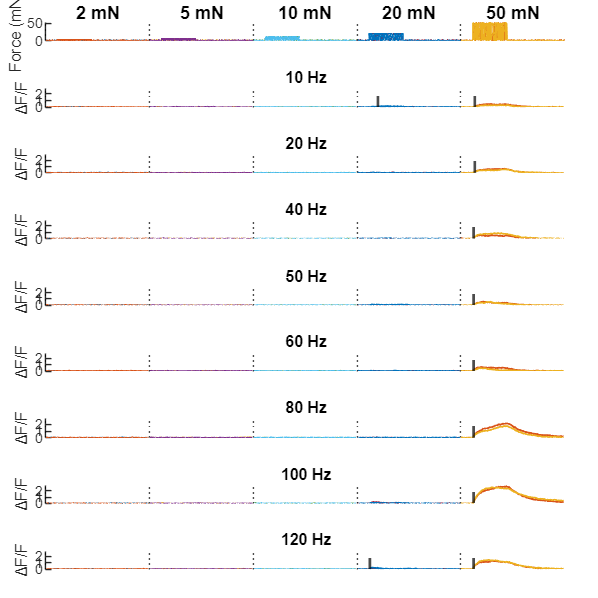

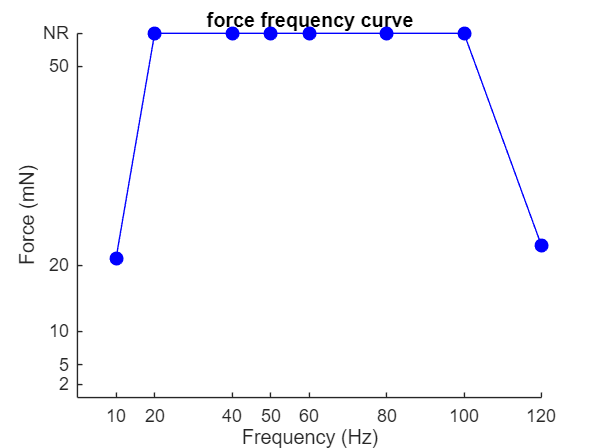

nCell = 16

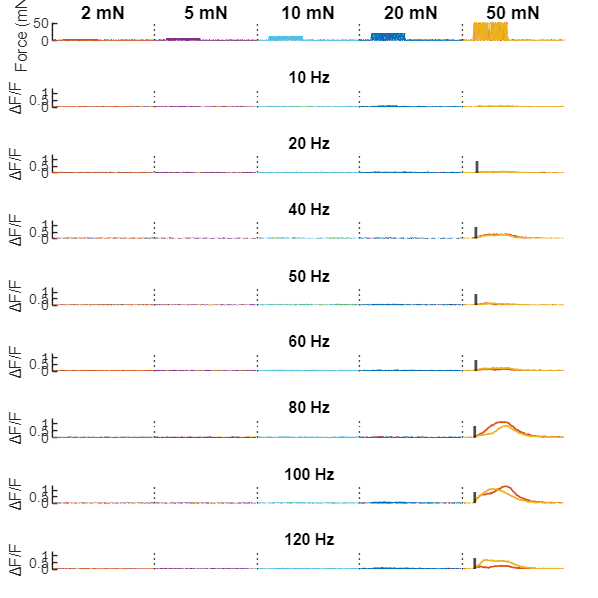

nCell = 17

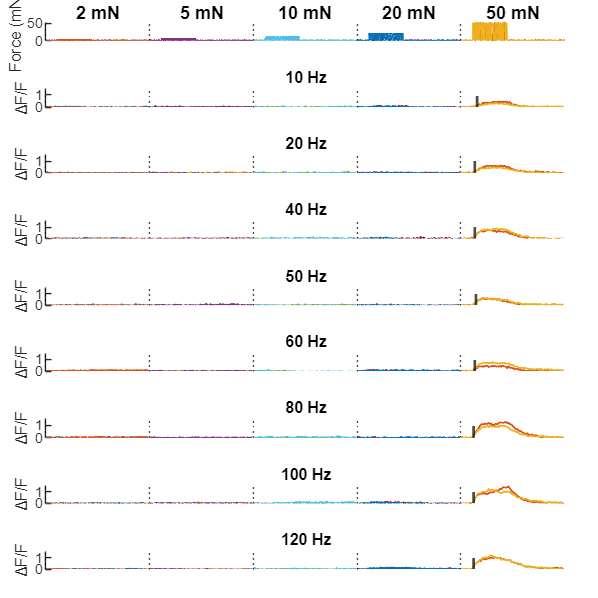

nCell = 18

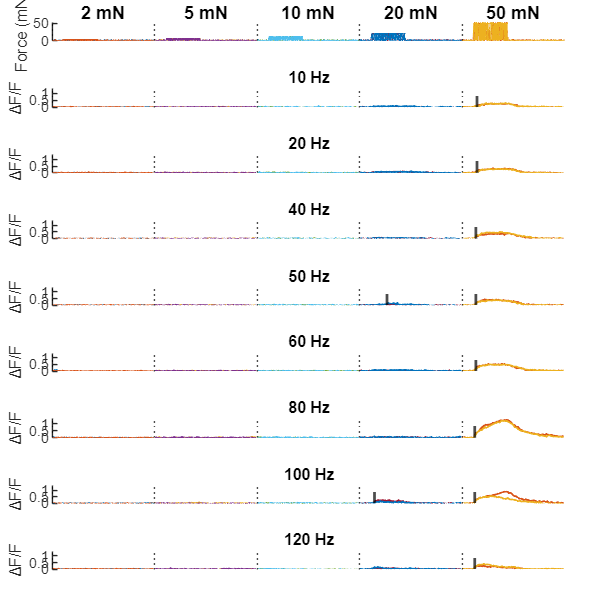

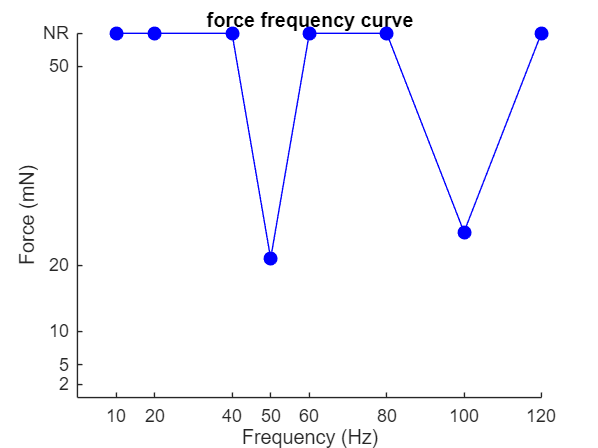

nCell = 19

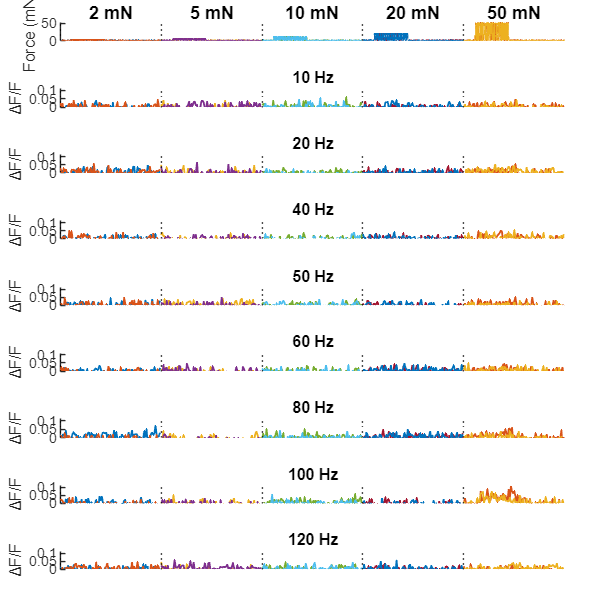

nCell = 20

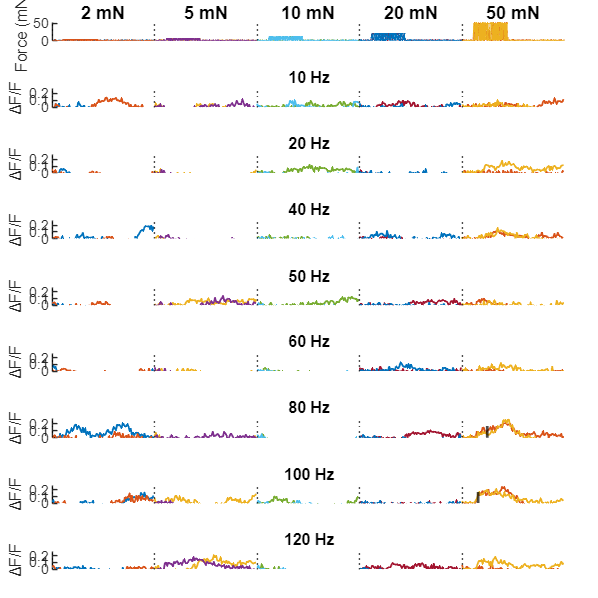

nCell = 21

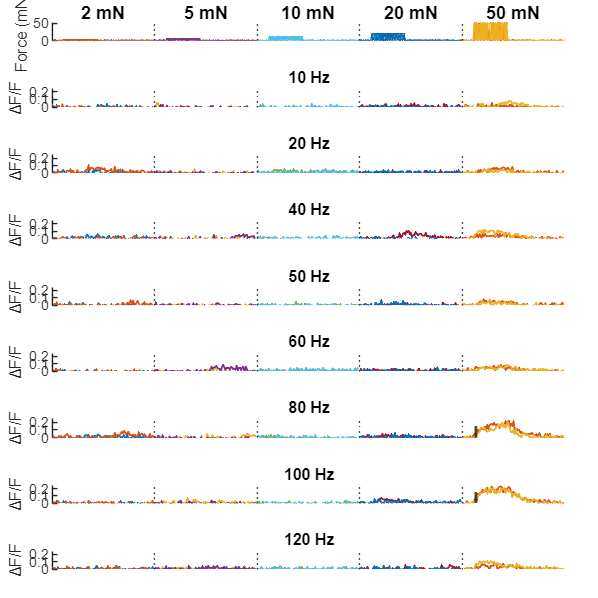

nCell = 22

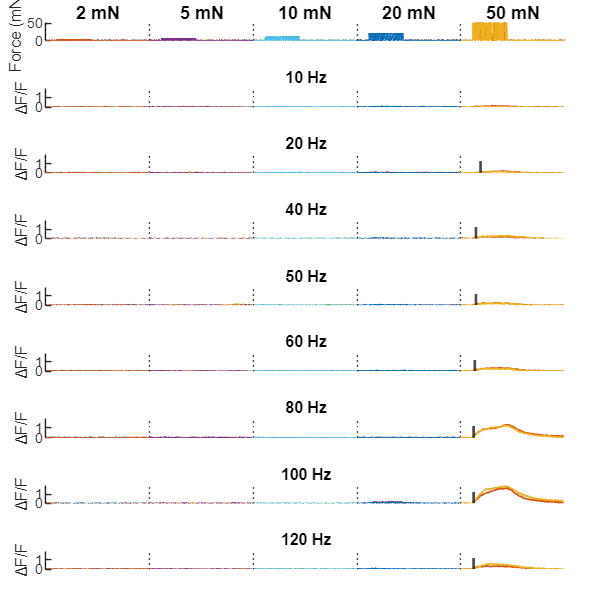

nCell = 23

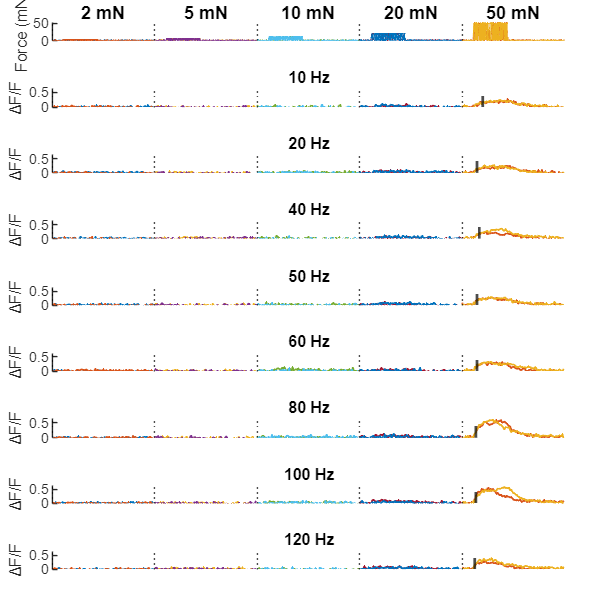

nCell = 24

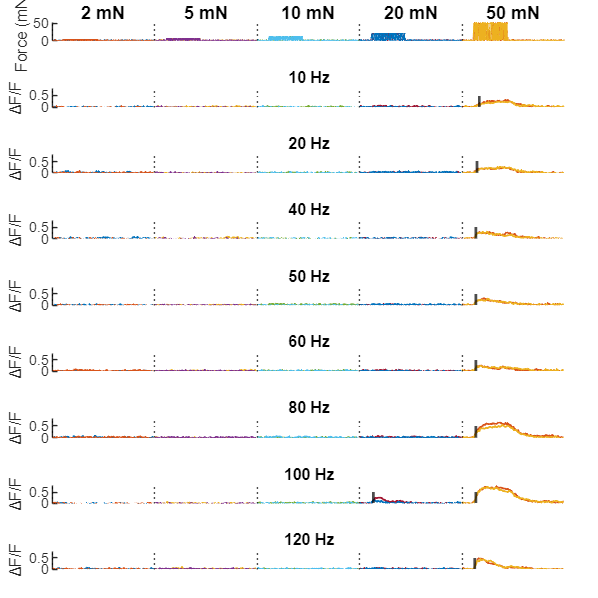

nCell = 25

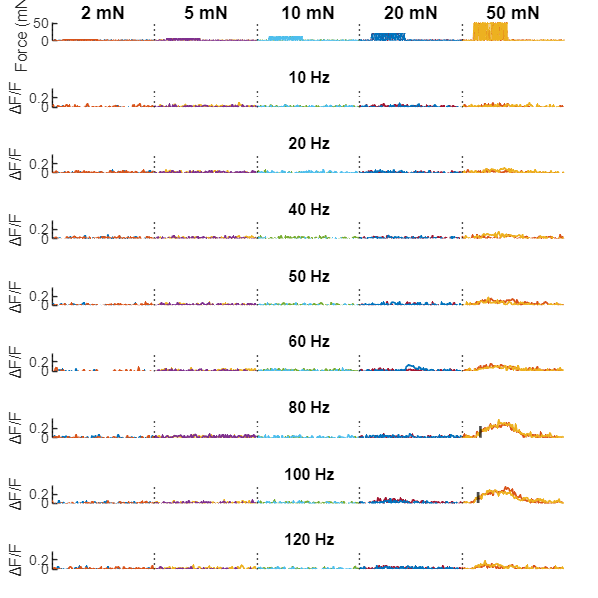

nCell = 26

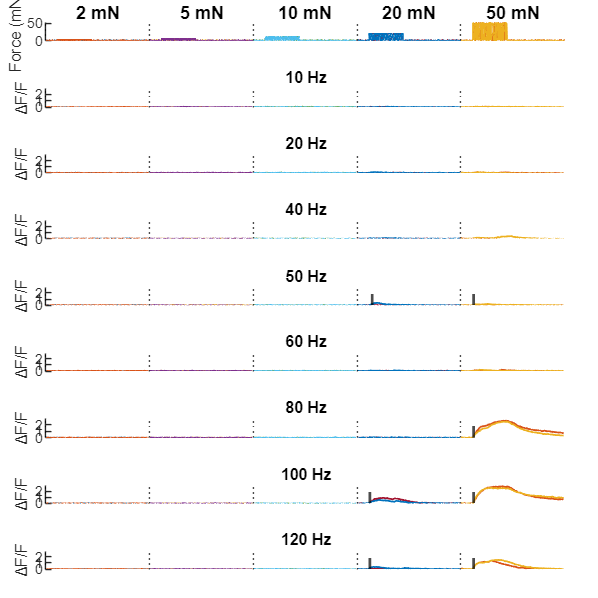

nCell = 27

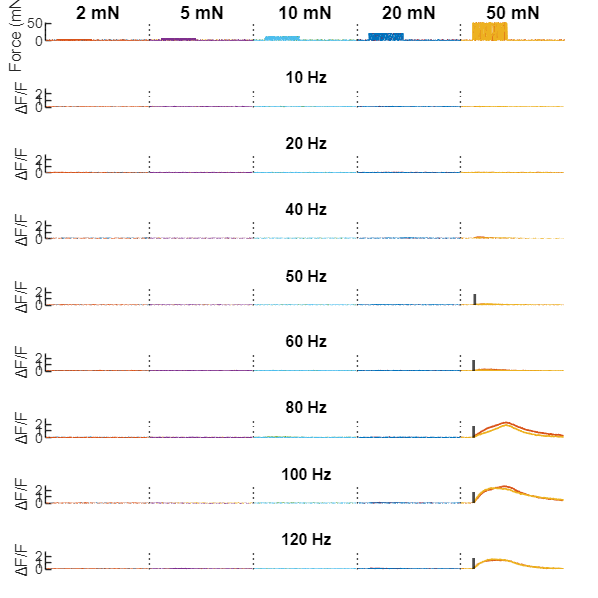

nCell = 28

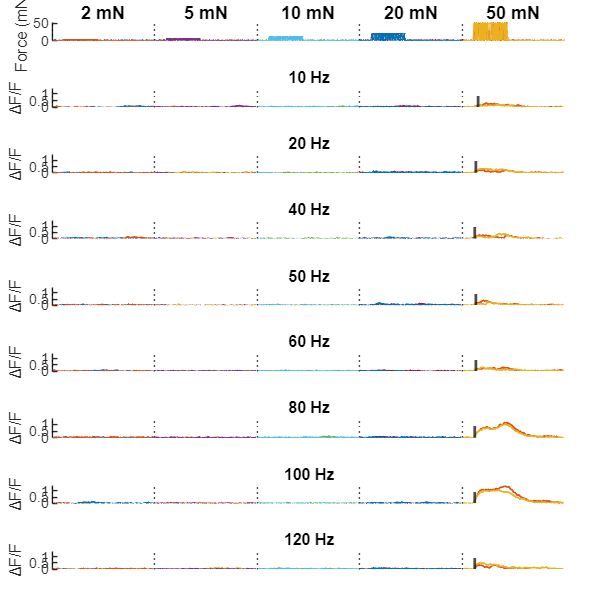

nCells = [1:size(normDeltaF,2)];
nStd = 5;
minConsec = 10;
freqTop = 10;
AllCell_freq_threshold = struct();

vibFolder = strcat(path,filename(1:end-4)) ;
if ~exist(vibFolder, 'dir')
    mkdir(vibFolder);
end
out = regexp(vibFolder, '(?<=calcium\\)(.*?)(?=\\preprocess)', 'match', 'once');

threshName = fullfile(vibFolder, [out,'_Neuron',sprintf('%d', nCells),'_threshVibStepSum.mat']);

for j = 1: numel(nCells)
    nCell = nCells(j)
    normDeltaFncell = normDeltaF(:,nCell);
    m = length(normDeltaFncell);
    nUnit = floor(m/numSweeps);
    newDeltaF = zeros(nUnit, numSweeps);
    for i = 1:numSweeps
        if i*nUnit < size(normDeltaF,1)
            newDeltaF(:, i) = normDeltaFncell((i-1) * nUnit +1 : i * nUnit) ;
        else
            newDeltaF(:, i) = [normDeltaFncell((i-1) * nUnit +1 : end); zeros(i * nUnit - size(normDeltaF,1), 1)];
        end
        % [~, newDeltaF(:, i), ~] = RobustDetrend(newDeltaF(:, i), 6, 0.975);
        newDeltaF(:,i) = newDeltaF(:,i) - mean(newDeltaF(1:baseline * fps, i)); %correct the baseline
    end

    Calcium_freq = zeros(size(newDeltaF,1)*nRepeat*length(sineAmplitude),length(sineFrequency));
    
    for i = 1:length(sineFrequency)
        freq_idx = find(sineBoth(:,2)== sineFrequency(i));
        calcium_temp = newDeltaF(:,freq_idx);
        Calcium_freq(:,i) = calcium_temp(:);
    end
    Cell_freq_forceThreshold = Align_forceSine_calcium(nCell, Calcium_freq,cfg,vibFolder,nStd,minConsec,freqTop);
    fieldname_cell = matlab.lang.makeValidName(sprintf('Neuron%d', nCell));
    AllCell_freq_threshold.(fieldname_cell) = Cell_freq_forceThreshold;
end


save(threshName,'AllCell_freq_threshold');

**Filter out low quality neurons if needed**

nCell = 1

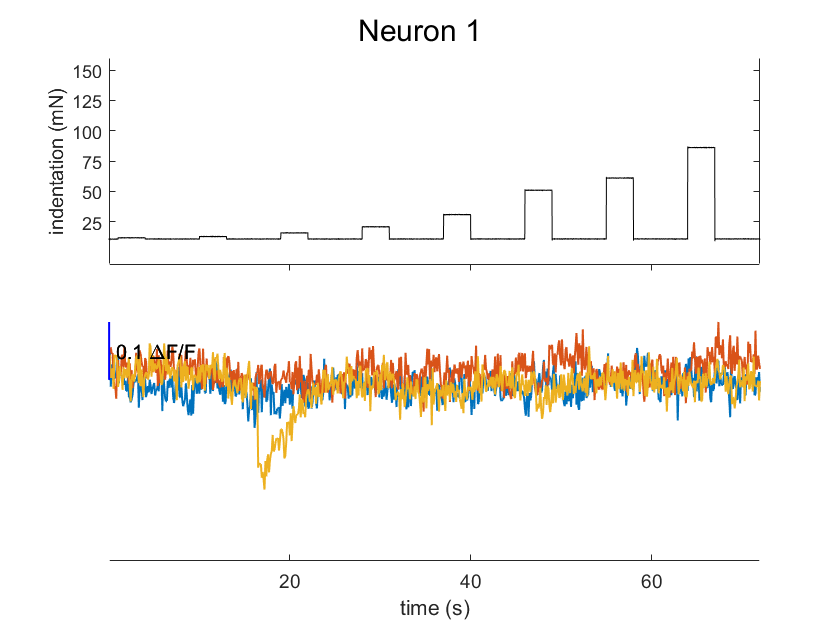

nCell = 2

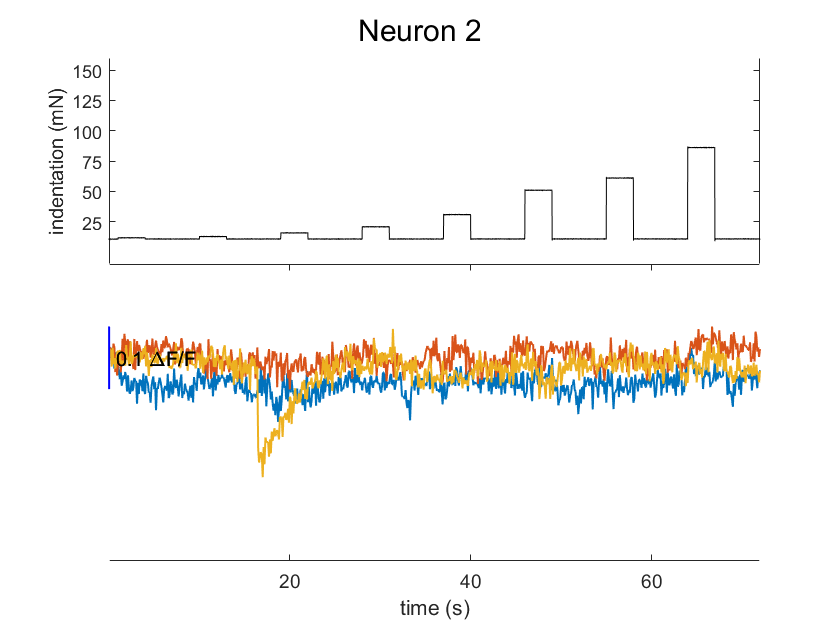

nCell = 3

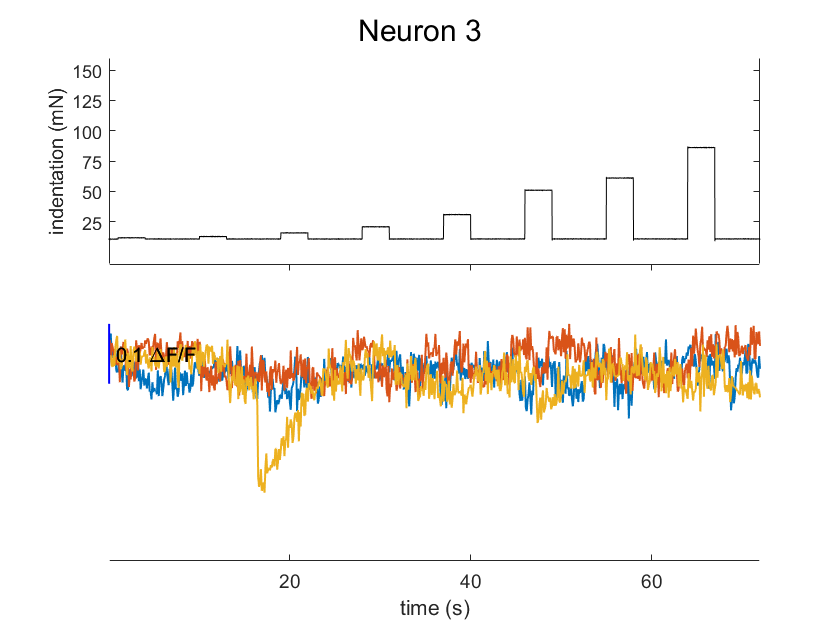

nCell = 4

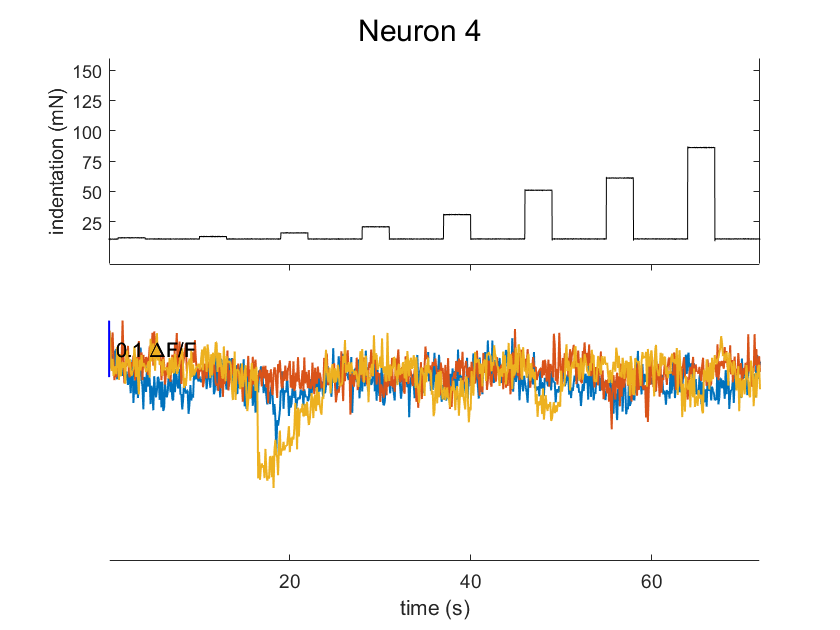

nCell = 1

ylCal =    -0.2101    0.6000


xEnd = 50.1000

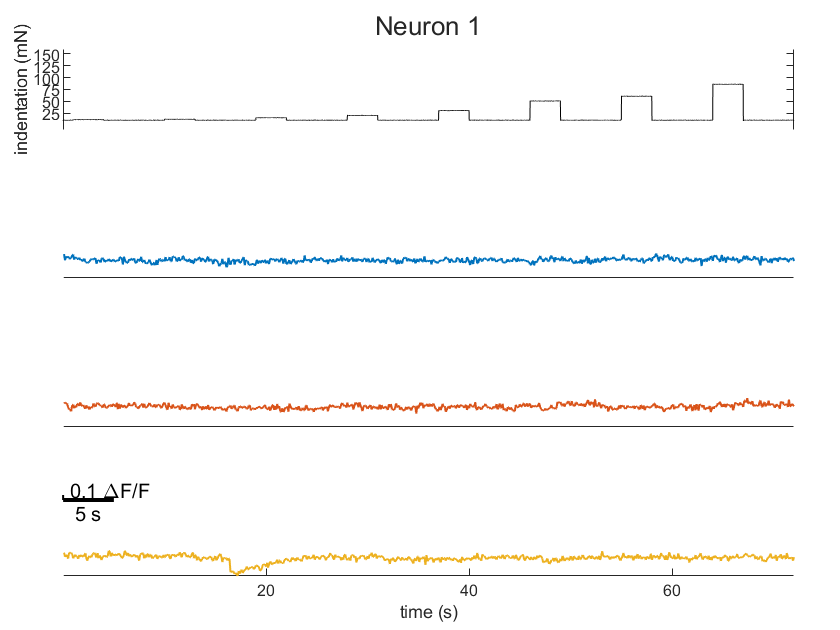

nCell = 2

ylCal =    -0.1924    0.6000


xEnd = 50.1000

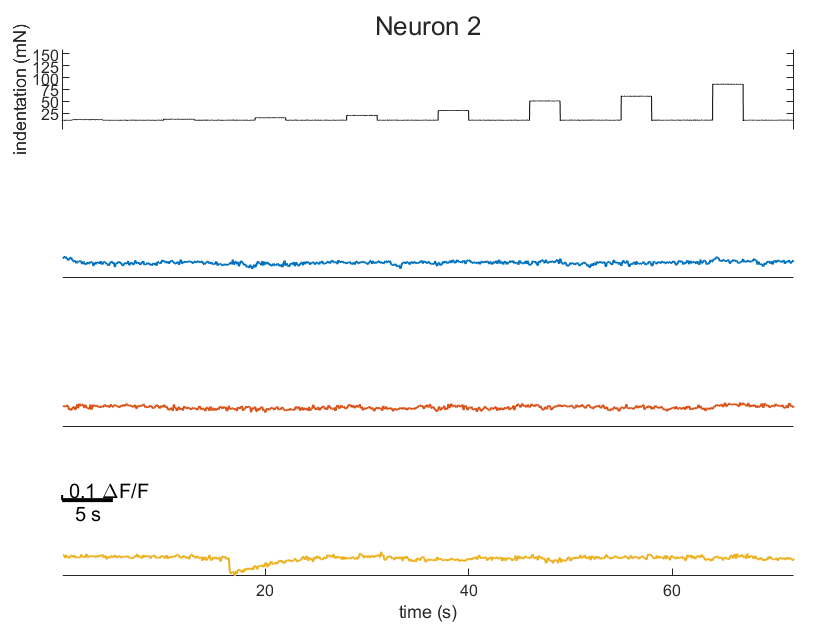

nCell = 3

ylCal =    -0.2294    0.6000


xEnd = 50.1000

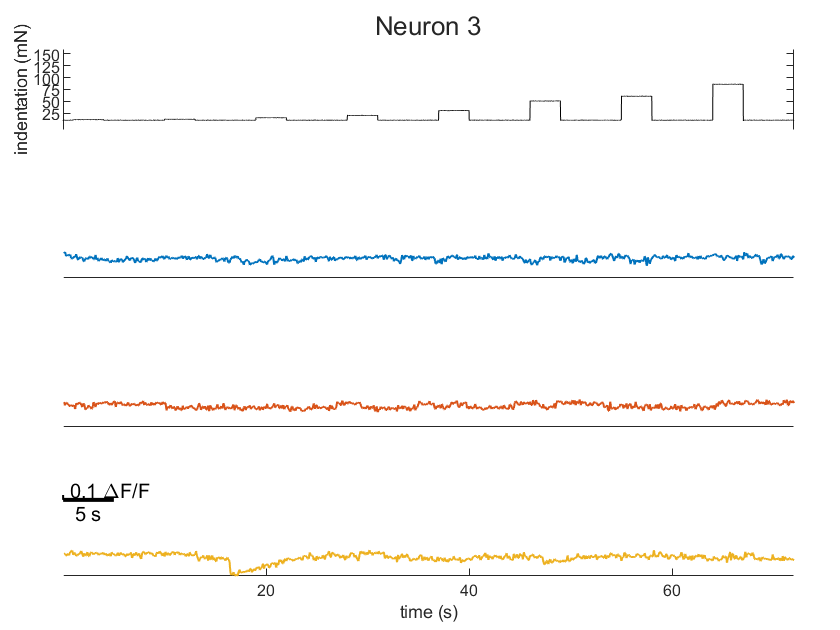

nCell = 4

ylCal =    -0.2242    0.6000


xEnd = 50.1000

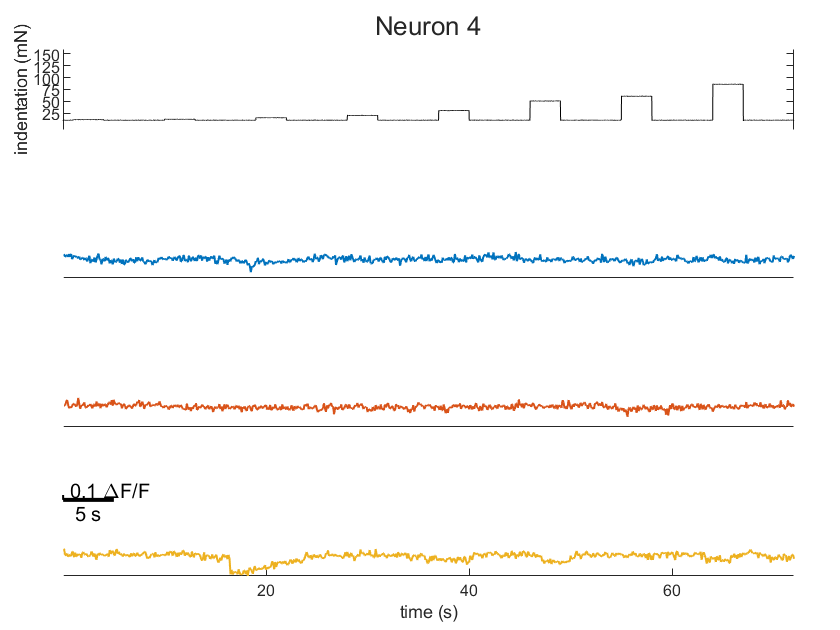

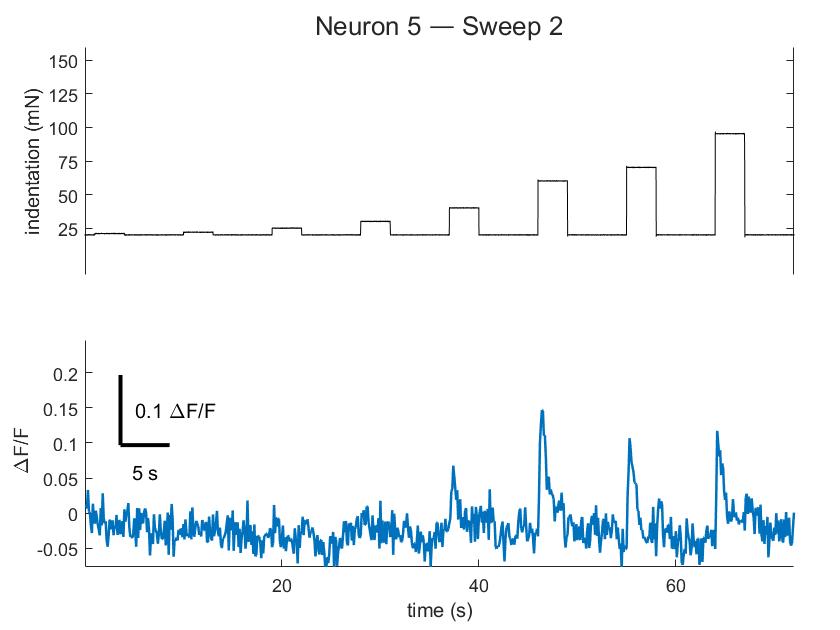

neurons_toskip = input('Enter neuron indices to skip (e.g., [1 2 5 7]): ');
fields = fieldnames(AllCell_freq_threshold);
fields_to_remove = fields(neurons_toskip);
AllCell_freq_threshold_filtered = rmfield(AllCell_freq_threshold, fields_to_remove);
threshName_filtered = strrep(threshName, '_threshVibStepSum.mat', '_threshVibStepSum_filtered.mat');
save(threshName_filtered, 'AllCell_freq_threshold_filtered');